# Deep Sudoku Solver

A computer vision system which takes an uncontrolled image of a sudoku puzzles, identifies its location, reads the puzzle, and solves it.

This example was originally put together for the [UK MATLAB Expo](http://www.matlabexpo.com/uk/index.html) 2018, for a talk entitled [Image processing and Computer Vision with MATLAB](http://www.matlabexpo.com/uk/2018/abstracts.html?expand=tracka&#sessiona5).

It is intended to demonstrate the use of a combination of deep learning and image procesing to solve a computer vision problem.

## Algorithm

The algorithm uses a combination of approaches from both deep learning and more 'traditional' image processing. The main steps of the algorithm are as follows:

- Find the sudoku puzzle in an image using deep learning (sematic segmentation)

- Extract each of the 81 number boxes in the puzzle using image processing.

- Read the number contained in each box using deep learning.

- Solve the puzzle using opimisation.

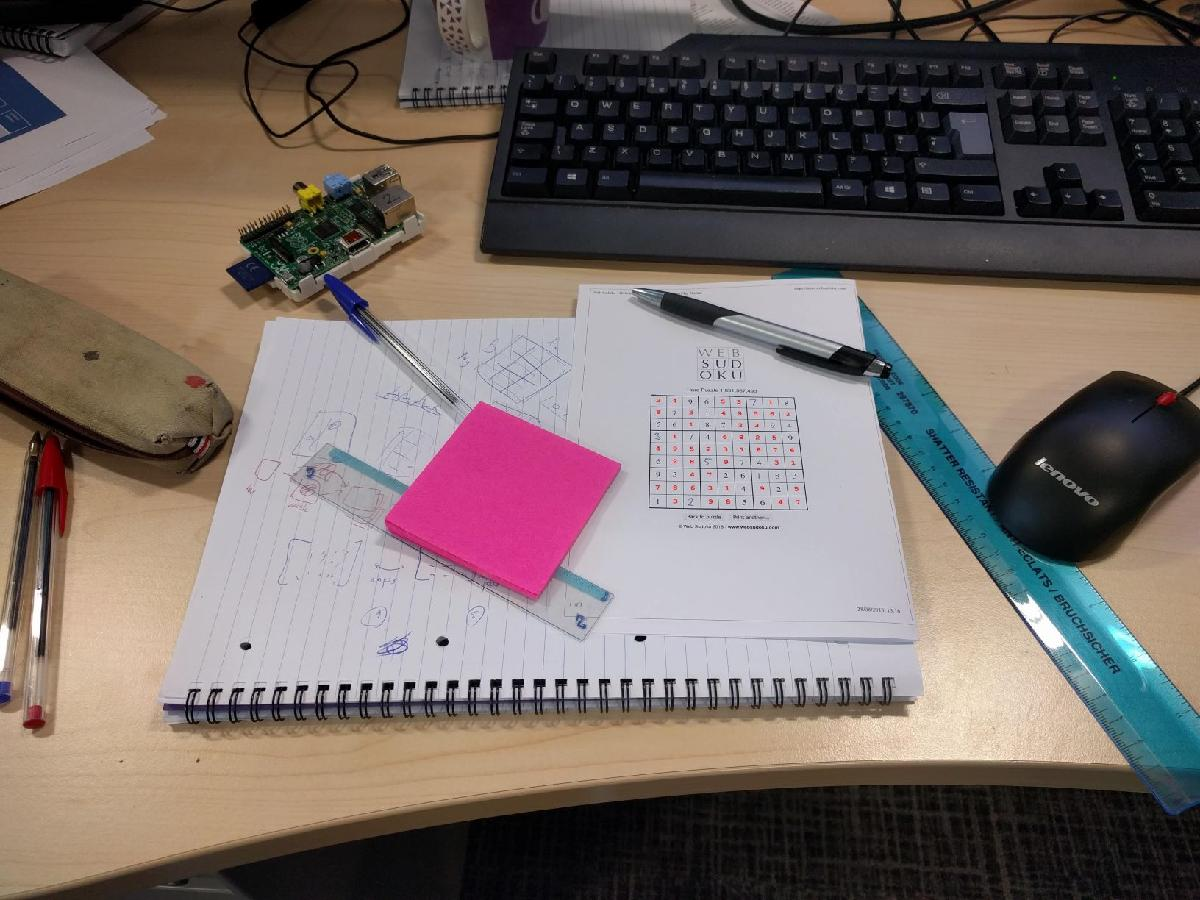

## Setup

This File Exchange submission contains all the required code to train the required neural networks in order to create a complete sudoku sovler.

Before using the code, navigate to the top level directory and run the function `install()` this will ensure all the required files and folders are added to the MATLAB path. (To remove these run `uninstall()`)

The required training data for the semantic segmentation training is included with the code. To generate the synthetic data for the number classification network the MNIST data set is required in the correct format, the function `sudoku.prepareMnistData()` will download and format correctly the required data. The data will be saved to disk so the function only needs to be run once.

## Training

To run the network training using the default options simply run the following two functions. (It is highly recommended to use a GPU during neural network training.)

sudoku.trainSemanticSegmentation();
sudoku.trainNumberNetwork();

Once training is complete the trained networks will be saved in the `models/` folder of the current working directory.

## Usage

Using the sudoku solver algorithm is done as follows:

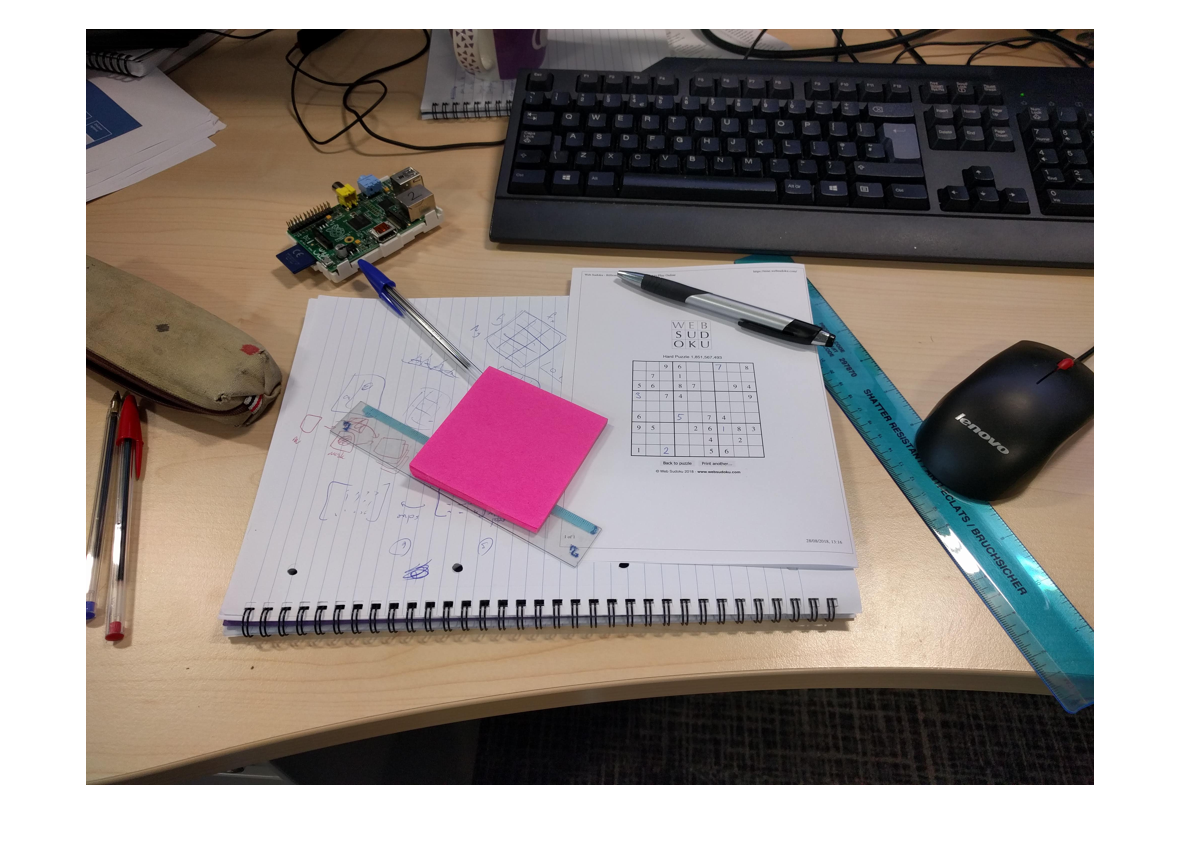

exampleImage = imread('docs/example.jpg');
imshow(imresize(exampleImage, 0.25));

solver = sudoku.PuzzleSolver();
[solution, outputs] = solver.process(exampleImage);

LP:                Optimal objective value is 29565.000000.                                         


Optimal solution found.

Intlinprog stopped at the root node because the
objective value is within a gap tolerance of the optimal value,
options.AbsoluteGapTolerance = 0 (the default value). The intcon variables are
integer within tolerance, options.IntegerTolerance = 1e-05 (the default value).



disp(solution);

     2     4     9     6     5     3     7     1     8
     8     7     3     1     4     9     5     6     2
     5     6     1     8     7     2     3     9     4
     3     1     7     4     6     8     2     5     9
     4     9     5     2     3     1     8     7     6
     6     2     8     5     9     7     4     3     1
     9     5     4     7     2     6     1     8     3
     7     8     6     3     1     4     9     2     5
     1     3     2     9     8     5     6     4     7



The intermediate steps in the algorithm can be accessed using the methods of the PuzzleSolver object, or visually inspected by plotting the different elements of the `outputs` cell array.

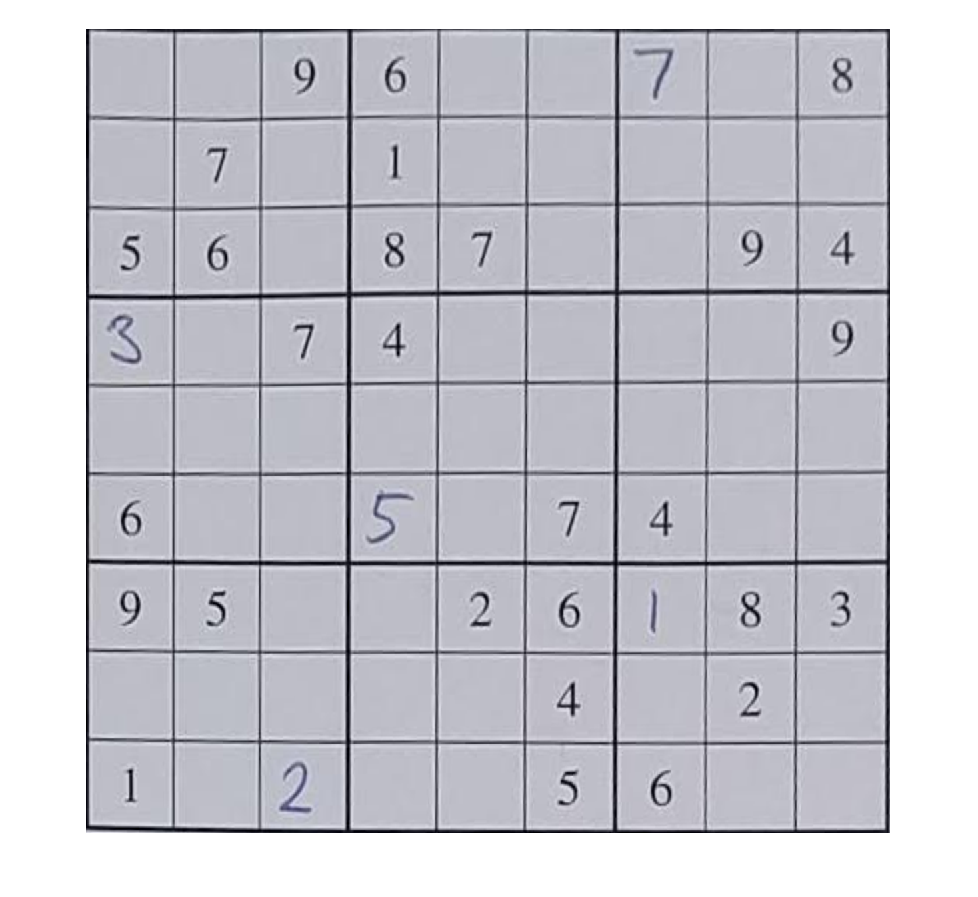

montage(outputs{6}');